clear all
close all
clc
directory_A = '..\05_Results\trial_more_segments\';
directory_B = '..\05_Results\trial_more_segments_no_degr\';

listing = dir(directory_A);
listing = listing(3:end);
listing = listing([listing(:).isdir] == false);

a = [];
parfor i = 1:length(listing)
    i
    a = [a;readtable(strcat(directory_A,listing(i).name))];
end

ans =
     1
ans =
     2
ans =
     3
ans =
     4
ans =
     5
ans =
     6
ans =
     7
ans =
     8
ans =
     9
ans =
    10
ans =
    12
ans =
    13
ans =
    15
ans =
    16
ans =
    18
ans =
    19
ans =
    21
ans =
    22
ans =
    24
ans =
    25
ans =
    27
ans =
    28
ans =
    30
ans =
    31
ans =
    14
ans =
    11
ans =
    17
ans =
    20
ans =
    23
ans =
    26
ans =
    29
ans =
    32
ans =
    40
ans =
    37
ans =
    38
ans =
    36
ans =
    39
ans =
    35
ans =
    34
ans =
    33
ans =
    48
ans =
    41
ans =
    45
ans =
    47
ans =
    42
ans =
    46
ans =
    43
ans =
    44
ans =
    53
ans =
    51
ans =
    52
ans =
    50
ans =
    49


deg1 = a(a.c_rate == 1,:);
deg2 = a(a.c_rate == 0.7,:);
deg3 = a(a.c_rate == 0.5,:);
deg4 = a(a.c_rate == 0.25,:);


listing = dir(directory_B);
listing = listing(3:end);
listing = listing([listing(:).isdir] == false);

a = [];
parfor i = 1:length(listing)
    i
    a = [a;readtable(strcat(directory_B,listing(i).name))];
end

ans =
     1
ans =
     3
ans =
     4
ans =
     6
ans =
     7
ans =
     8
ans =
     9
ans =
     2
ans =
    17
ans =
    18
ans =
    21
ans =
     5
ans =
    25
ans =
    26
ans =
    29
ans =
    33
ans =
    37
ans =
    10
ans =
    13
ans =
    14
ans =
    22
ans =
    30
ans =
    34
ans =
    38
ans =
    11
ans =
    15
ans =
    19
ans =
    23
ans =
    27
ans =
    31
ans =
    35
ans =
    39
ans =
    12
ans =
    16
ans =
    20
ans =
    24
ans =
    28
ans =
    32
ans =
    36
ans =
    40
ans =
    41
ans =
    51
ans =
    45
ans =
    49
ans =
    53
ans =
    47
ans =
    42
ans =
    52
ans =
    46
ans =
    55
ans =
    43
ans =
    44
ans =
    50
ans =
    54
ans =
    48
ans =
    56
ans =
    60
ans =
    63
ans =
    58
ans =
    64
ans =
    57
ans =
    62
ans =
    59
ans =
    61
ans =
    67
ans =
    66
ans =
    72
ans =
    65
ans =
    69
ans =
    71
ans =
    73
ans =
    68
ans =
    70
ans =
    76
ans =
    74
ans =
    75


nodeg1 = a(a.c_rate == 1,:);
nodeg2 = a(a.c_rate == 0.7,:);
nodeg3 = a(a.c_rate == 0.5,:);
nodeg4 = a(a.c_rate == 0.25,:);





deg1 = sortrows(deg1, 'p_co2');
deg2 = sortrows(deg2, 'p_co2');
deg3 = sortrows(deg3, 'p_co2');
deg4 = sortrows(deg4, 'p_co2');

nodeg1 = sortrows(nodeg1, 'p_co2');
nodeg2 = sortrows(nodeg2, 'p_co2');
nodeg3 = sortrows(nodeg3, 'p_co2');
nodeg4 = sortrows(nodeg4, 'p_co2');

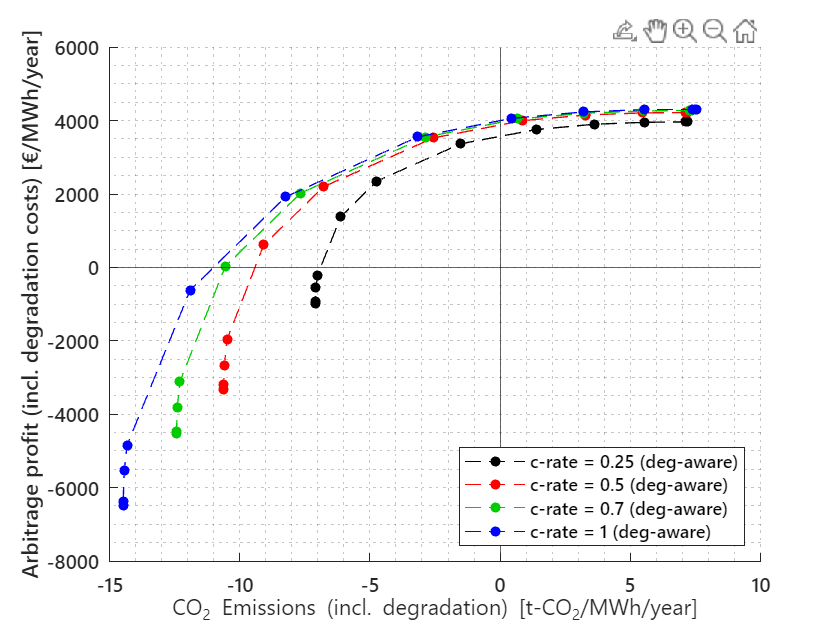

shelf_money_loss = (1/deg1.shelf_life_years)*(deg1.replacement_cost-deg1.salvage_value);
shelf_co2_loss = (1/deg1.shelf_life_years)*(deg1.life_cycle_emissions);

close all
figure
hold on
fontname(gcf, "Segoe UI")
plot((deg4.co2+deg4.real_degradation_co2-shelf_co2_loss)./deg4.batt_cap,(deg4.money-deg4.real_degradation_money+shelf_money_loss)./deg4.batt_cap*1000,'.--k','Color', [0,0,0]  ,'MarkerSize',15,'DisplayName',"c-rate = " + num2str(deg4.c_rate(1)) +  " (deg-aware)" )
plot((deg3.co2+deg3.real_degradation_co2-shelf_co2_loss)./deg3.batt_cap,(deg3.money-deg3.real_degradation_money+shelf_money_loss)./deg3.batt_cap*1000,'.--', 'Color', [1,0,0]  ,'MarkerSize',15,'DisplayName',"c-rate = " + num2str(deg3.c_rate(1)) +  " (deg-aware)" )
plot((deg2.co2+deg2.real_degradation_co2-shelf_co2_loss)./deg2.batt_cap,(deg2.money-deg2.real_degradation_money+shelf_money_loss)./deg2.batt_cap*1000,'.--', 'Color', [0,0.8,0],'MarkerSize',15,'DisplayName',"c-rate = " + num2str(deg2.c_rate(1))+ " (deg-aware)"   )
plot((deg1.co2+deg1.real_degradation_co2-shelf_co2_loss)./deg1.batt_cap,(deg1.money-deg1.real_degradation_money+shelf_money_loss)./deg1.batt_cap*1000,'.--', 'Color', [0,0,1]  ,'MarkerSize',15,'DisplayName',"c-rate = " + num2str(deg1.c_rate(1))+ " (deg-aware)"   )
grid minor
xline(0,'HandleVisibility','off')
yline(0,'HandleVisibility','off')
xlabel("CO_2 Emissions (incl. degradation) [t-CO_2/MWh/year]")
ylabel("Arbitrage profit (incl. degradation costs) [€/MWh/year]")
hold off
legend(Location="southeast")

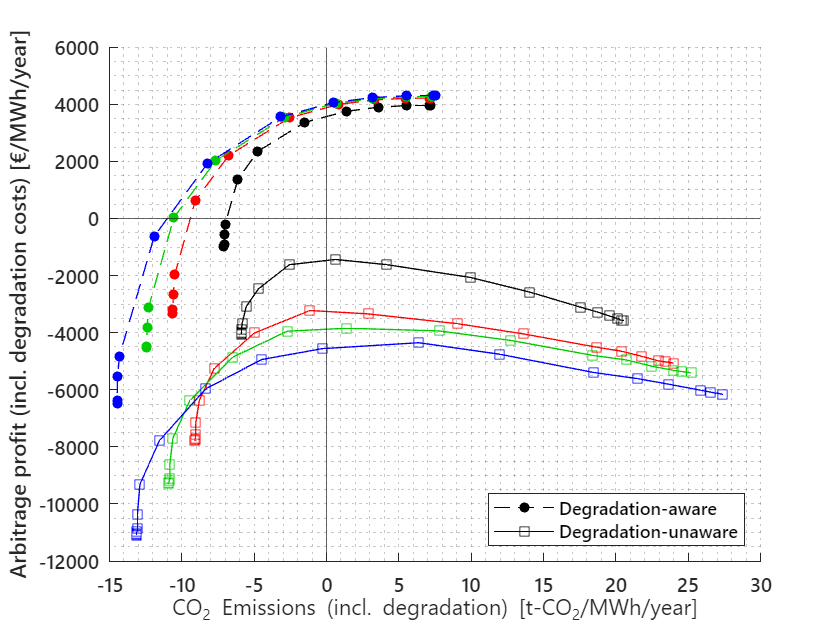

close all
figure
hold on
fontname(gcf, "Segoe UI")
plot((deg4.co2+deg4.real_degradation_co2-shelf_co2_loss)./deg4.batt_cap,(deg4.money-deg4.real_degradation_money+shelf_money_loss)./deg4.batt_cap*1000,'.--k','Color', [0,0,0]  ,'MarkerSize',15,'DisplayName',"c-rate = " + num2str(deg4.c_rate(1)) +  " (deg-aware)" )
plot((deg3.co2+deg3.real_degradation_co2-shelf_co2_loss)./deg3.batt_cap,(deg3.money-deg3.real_degradation_money+shelf_money_loss)./deg3.batt_cap*1000,'.--', 'Color', [1,0,0]  ,'MarkerSize',15,'DisplayName',"c-rate = " + num2str(deg3.c_rate(1)) +  " (deg-aware)" )
plot((deg2.co2+deg2.real_degradation_co2-shelf_co2_loss)./deg2.batt_cap,(deg2.money-deg2.real_degradation_money+shelf_money_loss)./deg2.batt_cap*1000,'.--', 'Color', [0,0.8,0],'MarkerSize',15,'DisplayName',"c-rate = " + num2str(deg2.c_rate(1))+ " (deg-aware)"   )
plot((deg1.co2+deg1.real_degradation_co2-shelf_co2_loss)./deg1.batt_cap,(deg1.money-deg1.real_degradation_money+shelf_money_loss)./deg1.batt_cap*1000,'.--', 'Color', [0,0,1]  ,'MarkerSize',15,'DisplayName',"c-rate = " + num2str(deg1.c_rate(1))+ " (deg-aware)"   )
plot((nodeg4.co2+nodeg4.real_degradation_co2-shelf_co2_loss)./nodeg4.batt_cap,(nodeg4.money-nodeg4.real_degradation_money+shelf_money_loss)./nodeg4.batt_cap*1000,'s-k','Color', [0,0,0]  ,'MarkerSize',6,'DisplayName',"c-rate = " + num2str(nodeg4.c_rate(1)) +  " (deg-unaware)" )
plot((nodeg3.co2+nodeg3.real_degradation_co2-shelf_co2_loss)./nodeg3.batt_cap,(nodeg3.money-nodeg3.real_degradation_money+shelf_money_loss)./nodeg3.batt_cap*1000,'s-', 'Color', [1,0,0]  ,'MarkerSize',6,'DisplayName',"c-rate = " + num2str(nodeg3.c_rate(1)) +  " (deg-unaware)" )
plot((nodeg2.co2+nodeg2.real_degradation_co2-shelf_co2_loss)./nodeg2.batt_cap,(nodeg2.money-nodeg2.real_degradation_money+shelf_money_loss)./nodeg2.batt_cap*1000,'s-', 'Color', [0,0.8,0],'MarkerSize',6,'DisplayName',"c-rate = " + num2str(nodeg2.c_rate(1))+ " (deg-unaware)"   )
plot((nodeg1.co2+nodeg1.real_degradation_co2-shelf_co2_loss)./nodeg1.batt_cap,(nodeg1.money-nodeg1.real_degradation_money+shelf_money_loss)./nodeg1.batt_cap*1000,'s-', 'Color', [0,0,1]  ,'MarkerSize',6,'DisplayName',"c-rate = " + num2str(nodeg1.c_rate(1))+ " (deg-unaware)"   )
grid minor
xline(0,'HandleVisibility','off')
yline(0,'HandleVisibility','off')
xlabel("CO_2 Emissions (incl. degradation) [t-CO_2/MWh/year]")
ylabel("Arbitrage profit (incl. degradation costs) [€/MWh/year]")
hold off
legend('Degradation-aware','','','','Degradation-unaware','','','',Location="southeast")

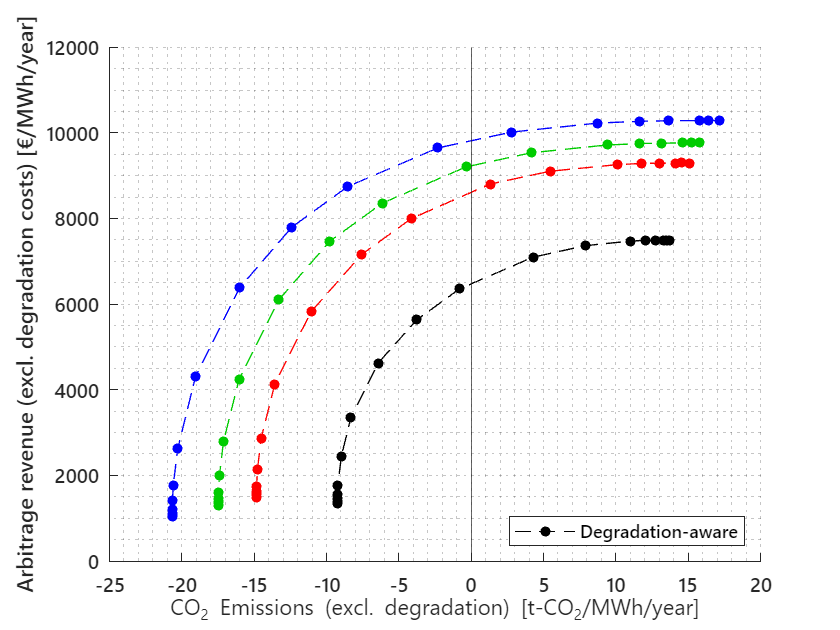

close all
figure
hold on
fontname(gcf, "Segoe UI")
plot((nodeg4.co2)./nodeg4.batt_cap,(nodeg4.money)./nodeg4.batt_cap*1000,'.--k','Color', [0,0,0]  ,'MarkerSize',15,'DisplayName',"c-rate = " + num2str(nodeg4.c_rate(1))+   " (deg-unaware)" )
plot((nodeg3.co2)./nodeg3.batt_cap,(nodeg3.money)./nodeg3.batt_cap*1000,'.--r','Color', [1,0,0]  ,'MarkerSize',15,'DisplayName',"c-rate = " + num2str(nodeg3.c_rate(1))+   " (deg-unaware)" )
plot((nodeg2.co2)./nodeg2.batt_cap,(nodeg2.money)./nodeg2.batt_cap*1000,'.--','Color', [0,0.8,0],'MarkerSize',15,'DisplayName',"c-rate = " + num2str(nodeg2.c_rate(1))+   " (deg-unaware)"   )
plot((nodeg1.co2)./nodeg1.batt_cap,(nodeg1.money)./nodeg1.batt_cap*1000,'.--b','Color', [0,0,1]  ,'MarkerSize',15,'DisplayName',"c-rate = " + num2str(nodeg1.c_rate(1))+   " (deg-unaware)"   )
grid minor
xline(0,'HandleVisibility','off')
yline(0,'HandleVisibility','off')
xlabel("CO_2 Emissions (excl. degradation) [t-CO_2/MWh/year]")
ylabel("Arbitrage revenue (excl. degradation costs) [€/MWh/year]")
hold off
legend(Location="southeast")

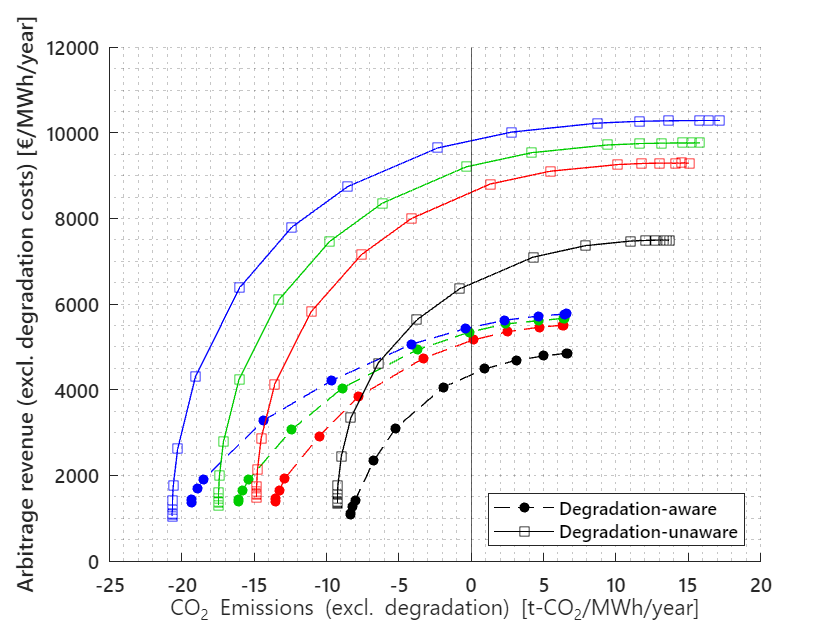

close all
figure
hold on
fontname(gcf, "Segoe UI")
plot((deg4.co2)./deg4.batt_cap,(deg4.money)./deg4.batt_cap*1000,'.--k','Color', [0,0,0]  ,'MarkerSize',15,'DisplayName',"c-rate = " + num2str(deg4.c_rate(1)) +  " (deg-aware)" )
plot((deg3.co2)./deg3.batt_cap,(deg3.money)./deg3.batt_cap*1000,'.--', 'Color', [1,0,0]  ,'MarkerSize',15,'DisplayName',"c-rate = " + num2str(deg3.c_rate(1)) +  " (deg-aware)" )
plot((deg2.co2)./deg2.batt_cap,(deg2.money)./deg2.batt_cap*1000,'.--', 'Color', [0,0.8,0],'MarkerSize',15,'DisplayName',"c-rate = " + num2str(deg2.c_rate(1))+ " (deg-aware)"   )
plot((deg1.co2)./deg1.batt_cap,(deg1.money)./deg1.batt_cap*1000,'.--', 'Color', [0,0,1]  ,'MarkerSize',15,'DisplayName',"c-rate = " + num2str(deg1.c_rate(1))+ " (deg-aware)"   )
plot((nodeg4.co2)./nodeg4.batt_cap,(nodeg4.money)./nodeg4.batt_cap*1000,'s-k','Color', [0,0,0]  ,'MarkerSize',6,'DisplayName',"c-rate = " + num2str(nodeg4.c_rate(1)) +  " (deg-unaware)" )
plot((nodeg3.co2)./nodeg3.batt_cap,(nodeg3.money)./nodeg3.batt_cap*1000,'s-', 'Color', [1,0,0]  ,'MarkerSize',6,'DisplayName',"c-rate = " + num2str(nodeg3.c_rate(1)) +  " (deg-unaware)" )
plot((nodeg2.co2)./nodeg2.batt_cap,(nodeg2.money)./nodeg2.batt_cap*1000,'s-', 'Color', [0,0.8,0],'MarkerSize',6,'DisplayName',"c-rate = " + num2str(nodeg2.c_rate(1))+ " (deg-unaware)"   )
plot((nodeg1.co2)./nodeg1.batt_cap,(nodeg1.money)./nodeg1.batt_cap*1000,'s-', 'Color', [0,0,1]  ,'MarkerSize',6,'DisplayName',"c-rate = " + num2str(nodeg1.c_rate(1))+ " (deg-unaware)"   )
grid minor
xline(0,'HandleVisibility','off')
yline(0,'HandleVisibility','off')
xlabel("CO_2 Emissions (excl. degradation) [t-CO_2/MWh/year]")
ylabel("Arbitrage revenue (excl. degradation costs) [€/MWh/year]")
hold off
legend('Degradation-aware','','','','Degradation-unaware','','','',Location="southeast")

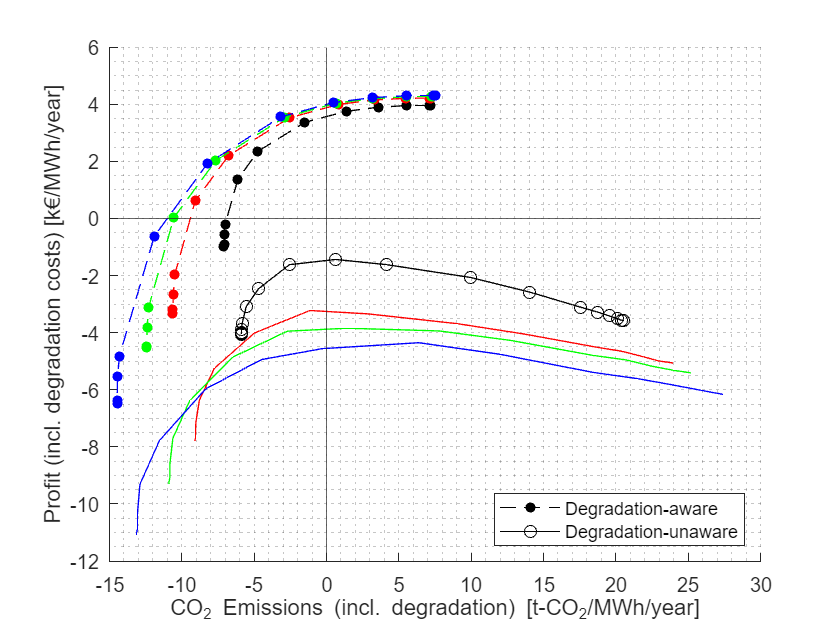

shelf_money_loss = (1/deg1.shelf_life_years)*(deg1.replacement_cost-deg1.salvage_value);
shelf_co2_loss = (1/deg1.shelf_life_years)*(deg1.life_cycle_emissions);

close all
figure
hold on
plot((deg4.co2+deg4.real_degradation_co2-shelf_co2_loss)./deg4.batt_cap,(deg4.money-deg4.real_degradation_money+shelf_money_loss)./deg4.batt_cap,'.--k','MarkerSize',15,'DisplayName',"c-rate = " + num2str(deg4.c_rate(1)) +  " (deg-aware)")
plot((deg3.co2+deg3.real_degradation_co2-shelf_co2_loss)./deg3.batt_cap,(deg3.money-deg3.real_degradation_money+shelf_money_loss)./deg3.batt_cap,'.--r','MarkerSize',15,'DisplayName',"c-rate = " + num2str(deg3.c_rate(1)) +  " (deg-aware)")
plot((deg2.co2+deg2.real_degradation_co2-shelf_co2_loss)./deg2.batt_cap,(deg2.money-deg2.real_degradation_money+shelf_money_loss)./deg2.batt_cap,'.--g','MarkerSize',15,'DisplayName',"c-rate = " + num2str(deg2.c_rate(1))+ " (deg-aware)")
plot((deg1.co2+deg1.real_degradation_co2-shelf_co2_loss)./deg1.batt_cap,(deg1.money-deg1.real_degradation_money+shelf_money_loss)./deg1.batt_cap,'.--b','MarkerSize',15,'DisplayName',"c-rate = " + num2str(deg1.c_rate(1))+ " (deg-aware)")
grid minor
xline(0,'HandleVisibility','off')
yline(0,'HandleVisibility','off')
xlabel("CO_2 Emissions (incl. degradation) [t-CO_2/MWh/year]")
ylabel("Profit (incl. degradation costs) [k€/MWh/year]")
plot((nodeg4.co2+nodeg4.real_degradation_co2-shelf_co2_loss)./nodeg4.batt_cap,(nodeg4.money-nodeg4.real_degradation_money+shelf_money_loss)./nodeg4.batt_cap,'o-k','DisplayName',"c-rate = " + num2str(nodeg4.c_rate(1))+ " (deg-unaware)")
plot((nodeg3.co2+nodeg3.real_degradation_co2-shelf_co2_loss)./nodeg3.batt_cap,(nodeg3.money-nodeg3.real_degradation_money+shelf_money_loss)./nodeg3.batt_cap,'r','DisplayName',"c-rate = " + num2str(nodeg3.c_rate(1))+ " (deg-unaware)")
plot((nodeg2.co2+nodeg2.real_degradation_co2-shelf_co2_loss)./nodeg2.batt_cap,(nodeg2.money-nodeg2.real_degradation_money+shelf_money_loss)./nodeg2.batt_cap,'g','DisplayName',"c-rate = " + num2str(nodeg2.c_rate(1))+ " (deg-unaware)")
plot((nodeg1.co2+nodeg1.real_degradation_co2-shelf_co2_loss)./nodeg1.batt_cap,(nodeg1.money-nodeg1.real_degradation_money+shelf_money_loss)./nodeg1.batt_cap,'b','DisplayName',"c-rate = " + num2str(nodeg1.c_rate(1))+ " (deg-unaware)")
hold off
legend(Location="southeast")

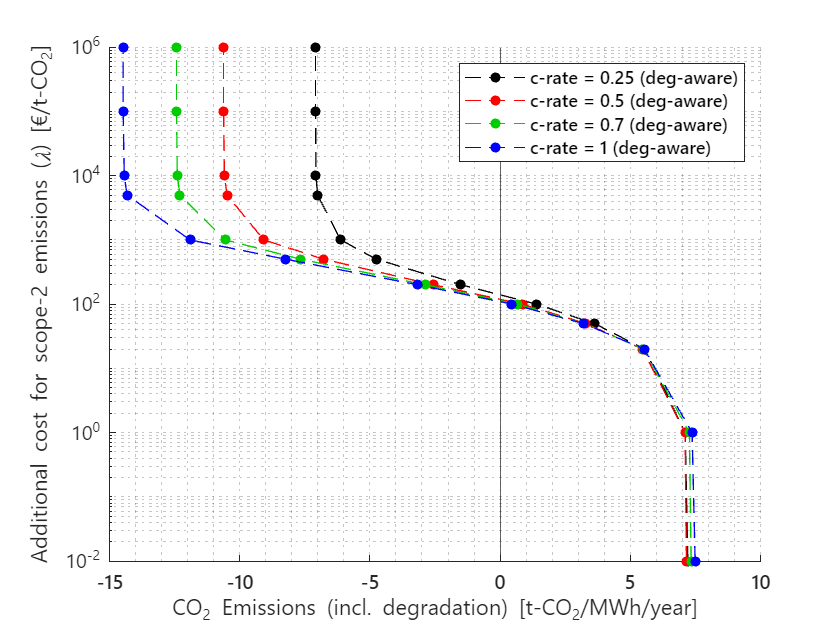

close all
figure
hold on
semilogx((deg4.co2+deg4.real_degradation_co2-shelf_co2_loss)./deg4.batt_cap,1000*deg4.p_co2,'.--k','Color', [0,0,0]  ,'MarkerSize',15,'DisplayName',"c-rate = " + num2str(deg4.c_rate(1)) +  " (deg-aware)")
semilogx((deg3.co2+deg3.real_degradation_co2-shelf_co2_loss)./deg3.batt_cap,1000*deg3.p_co2,'.--r','Color', [1,0,0]  ,'MarkerSize',15,'DisplayName',"c-rate = " + num2str(deg3.c_rate(1)) +  " (deg-aware)")
semilogx((deg2.co2+deg2.real_degradation_co2-shelf_co2_loss)./deg2.batt_cap,1000*deg2.p_co2,'.--g','Color', [0,0.8,0],'MarkerSize',15,'DisplayName',"c-rate = " + num2str(deg2.c_rate(1))+ " (deg-aware)")
semilogx((deg1.co2+deg1.real_degradation_co2-shelf_co2_loss)./deg1.batt_cap,1000*deg1.p_co2,'.--b','Color', [0,0,1]  ,'MarkerSize',15,'DisplayName',"c-rate = " + num2str(deg1.c_rate(1))+ " (deg-aware)")
xline(0,'HandleVisibility','off')
fontname(gcf, "Segoe UI")
grid minor
xlabel("CO_2 Emissions (incl. degradation) [t-CO_2/MWh/year]")
ylabel("Additional cost for scope-2 emissions (\lambda) [€/t-CO_2]")
hold off
legend
set(gca, 'YScale', 'log')

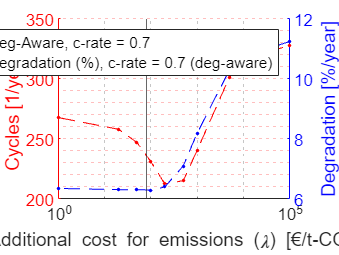


close all
figure
yyaxis left
set(gca,'YColor','r')
hold on
plot(1000*deg2.p_co2,deg2.cycles,'r.--','MarkerSize',5,'DisplayName',"Deg-Aware, c-rate = " + num2str(deg2.c_rate(1)))
% plot(1000*nodeg2.p_co2,nodeg2.cycles,'r.-','MarkerSize',5,'DisplayName',"Deg-Unaware, c-rate = " + num2str(nodeg2.c_rate(1)))

xline(80,'HandleVisibility','off')
ylabel("Cycles [1/year]",Color=[1,0,0])


yyaxis right
set(gca,'YColor','blue')
plot(1000*deg2.p_co2, deg2.degradation*100, 'b.--','MarkerSize',5,'DisplayName',"Degradation (%), c-rate = " + num2str(deg2.c_rate(1)) +  " (deg-aware)")
% plot(1000*nodeg2.p_co2, nodeg2.degradation*100, 'b.-','MarkerSize',5,'DisplayName',"Degradation (%), c-rate = " + num2str(nodeg2.c_rate(1)) +  " (deg-unaware)")
grid minor
ylabel("Degradation [%/year]",Color=[0,0,1])
yyaxis left
xlabel("Additional cost for emissions (\lambda) [€/t-CO_2]")
hold off
legend
set(gca, 'XScale', 'log')
xlim([1,1e5])

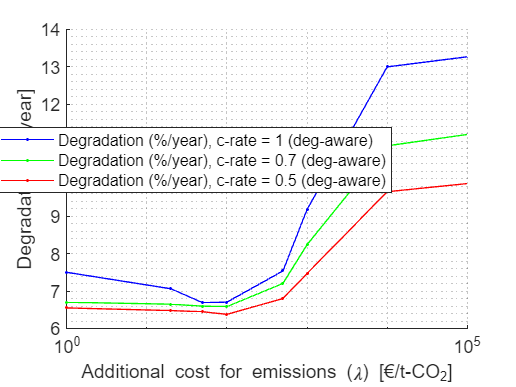


close all
figure
hold on
plot(1000*deg1.p_co2, deg1.degradation*100, 'b.-','MarkerSize',5,'DisplayName',"Degradation (%/year), c-rate = " + num2str(deg1.c_rate(1)) +  " (deg-aware)")
plot(1000*deg2.p_co2, deg2.degradation*100, 'g.-','MarkerSize',5,'DisplayName',"Degradation (%/year), c-rate = " + num2str(deg2.c_rate(1)) +  " (deg-aware)")
plot(1000*deg3.p_co2, deg3.degradation*100, 'r.-','MarkerSize',5,'DisplayName',"Degradation (%/year), c-rate = " + num2str(deg3.c_rate(1)) +  " (deg-aware)")
hold off
grid minor
ylabel("Degradation [%/year]")
xlabel("Additional cost for emissions (\lambda) [€/t-CO_2]")
hold off
xlim([1,1e5])
legend
set(gca, 'XScale', 'log')

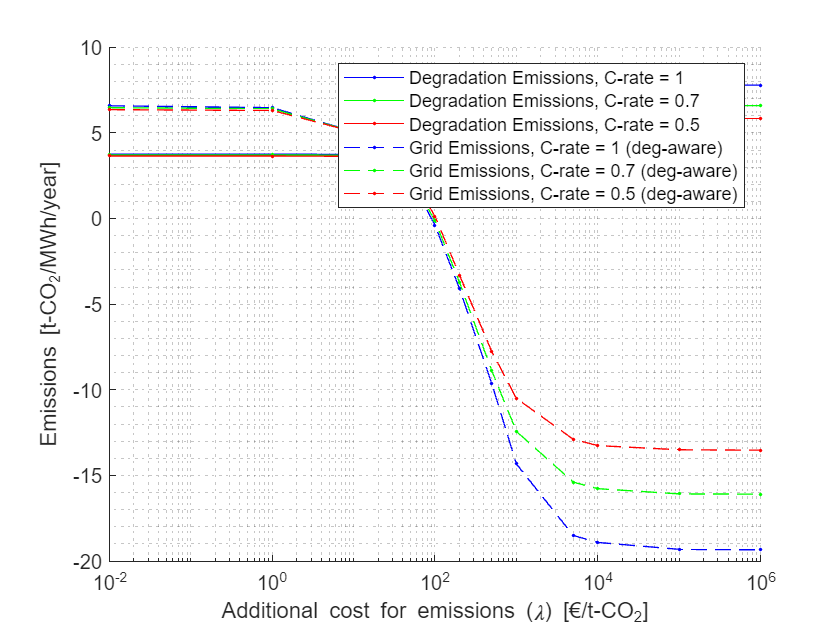

close all
figure
hold on
plot(1000*deg1.p_co2, deg1.degradation_co2./deg1.batt_cap(1), 'b.-','MarkerSize',5,'DisplayName',"Degradation Emissions, C-rate = " + num2str(deg1.c_rate(1)))
plot(1000*deg2.p_co2, deg2.degradation_co2./deg1.batt_cap(1), 'g.-','MarkerSize',5,'DisplayName',"Degradation Emissions, C-rate = " + num2str(deg2.c_rate(1)))
plot(1000*deg3.p_co2, deg3.degradation_co2./deg1.batt_cap(1), 'r.-','MarkerSize',5,'DisplayName',"Degradation Emissions, C-rate = " + num2str(deg3.c_rate(1)))
hold off
ylabel("Emissions [t-CO_2/MWh/year]")
hold on
plot(1000*deg1.p_co2, deg1.co2./deg1.batt_cap(1), 'b.--','MarkerSize',5,'DisplayName',"Grid Emissions, C-rate = " + num2str(deg1.c_rate(1)) +  " (deg-aware)")
plot(1000*deg2.p_co2, deg2.co2./deg1.batt_cap(1), 'g.--','MarkerSize',5,'DisplayName',"Grid Emissions, C-rate = " + num2str(deg2.c_rate(1)) +  " (deg-aware)")
plot(1000*deg3.p_co2, deg3.co2./deg1.batt_cap(1), 'r.--','MarkerSize',5,'DisplayName',"Grid Emissions, C-rate = " + num2str(deg3.c_rate(1)) +  " (deg-aware)")
hold off
grid minor
xlabel("Additional cost for emissions (\lambda) [€/t-CO_2]")
hold off
legend
set(gca, 'XScale', 'log')

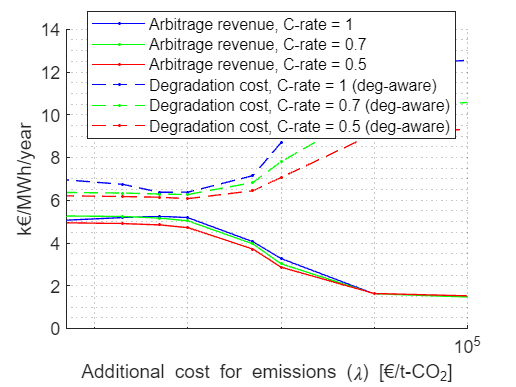

close all
figure
hold on
plot(1000*deg1.p_co2, deg1.money./deg1.batt_cap(1), 'b.-','MarkerSize',5,'DisplayName',"Arbitrage revenue, C-rate = " + num2str(deg1.c_rate(1)))
plot(1000*deg2.p_co2, deg2.money./deg1.batt_cap(1), 'g.-','MarkerSize',5,'DisplayName',"Arbitrage revenue, C-rate = " + num2str(deg2.c_rate(1)))
plot(1000*deg3.p_co2, deg3.money./deg1.batt_cap(1), 'r.-','MarkerSize',5,'DisplayName',"Arbitrage revenue, C-rate = " + num2str(deg3.c_rate(1)))
hold off
ylabel("k€/MWh/year")
hold on
plot(1000*deg1.p_co2, deg1.real_degradation_money./deg1.batt_cap(1), 'b.--','MarkerSize',5,'DisplayName',"Degradation cost, C-rate = " + num2str(deg1.c_rate(1)) +  " (deg-aware)")
plot(1000*deg2.p_co2, deg2.real_degradation_money./deg1.batt_cap(1), 'g.--','MarkerSize',5,'DisplayName',"Degradation cost, C-rate = " + num2str(deg2.c_rate(1)) +  " (deg-aware)")
plot(1000*deg3.p_co2, deg3.real_degradation_money./deg1.batt_cap(1), 'r.--','MarkerSize',5,'DisplayName',"Degradation cost, C-rate = " + num2str(deg3.c_rate(1)) +  " (deg-aware)")
hold off
grid minor
xlabel("Additional cost for emissions (\lambda) [€/t-CO_2]")
hold off
legend
set(gca, 'XScale', 'log')
xlim([5,1e5])

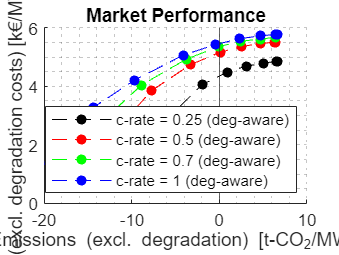

close all
figure
hold on
plot((deg4.co2)./deg4.batt_cap,(deg4.money)./deg4.batt_cap,'.--k','MarkerSize',15,'DisplayName',"c-rate = " + num2str(deg4.c_rate(1)) +  " (deg-aware)")
plot((deg3.co2)./deg3.batt_cap,(deg3.money)./deg3.batt_cap,'.--r','MarkerSize',15,'DisplayName',"c-rate = " + num2str(deg3.c_rate(1)) +  " (deg-aware)")
plot((deg2.co2)./deg2.batt_cap,(deg2.money)./deg2.batt_cap,'.--g','MarkerSize',15,'DisplayName',"c-rate = " + num2str(deg2.c_rate(1))+ " (deg-aware)")
plot((deg1.co2)./deg1.batt_cap,(deg1.money)./deg1.batt_cap,'.--b','MarkerSize',15,'DisplayName',"c-rate = " + num2str(deg1.c_rate(1))+ " (deg-aware)")
grid minor
xline(0,'HandleVisibility','off')
yline(0,'HandleVisibility','off')
xlabel("CO_2 Emissions (excl. degradation) [t-CO_2/MWh/year]")
ylabel("Profit (excl. degradation costs) [k€/MWh/year]")
hold off
title("Market Performance")
legend(Location="southeast")

a = a(a.c_rate == 0.7,:)

a =
  0×32 empty table


a = a(a.horizon == 48,:)

a =
  0×32 empty table


a = sortrows(a,"p_co2")

a =
  0×32 empty table


plot(a.co2,a.money)
plot(a.co2+a.degradation_co2,a.money-a.degradation_money)
plot(a.co2+a.real_degradation_co2,a.money-a.real_degradation_money)

plot(a.degradation_co2.*a.p_co2, a.degradation_money)